clear
% Información del archivo .h5
path = "..\hdf5\A_RS_140819\LFP.h5";
filename = strrep(path, '\', '\\');
dataset = '/LFP';
info = h5info(filename, dataset);
num_times = info.Dataspace.Size(1);

signal = h5read(filename, dataset);

f=2; x=0; y=1;
for time_points=[1e3, 1e4, 1e5, 1e6]
    time_points
    narray=1;
    mean_path = sprintf("subsample_espacial_temporal\\mean_t_%d_f_%d.mat", time_points, f);
    dfa_path = sprintf("subsample_espacial_temporal\\dfa_t_%d_f_%d.mat", time_points, f);
    avalanches_path = sprintf("subsample_espacial_temporal\\ava_t_%d_f_%d.mat", time_points, f);
    
    space_mask = subsample_mask(f, x, y) & floor((0:1023)/64)==narray;
    time_mask = sort(randi(num_times, time_points, 1));
    subsample_mean(signal, space_mask, time_mask, mean_path);
    
    box_lengths=floor(logspace(1, log10(time_points), 10))';
    subsample_dfa(mean_path, dfa_path, box_lengths);
    
    threshold=50;
    subsample_avalanches(mean_path, avalanches_path, threshold);
end

time_points = 1000

time_points = 10000

time_points = 100000

time_points = 1000000

f=1; x=0; y=1;
E = (10:19);
for e=E
    time_points=2.^e;
    narray=1;
    mean_path = sprintf("subsample_espacial_temporal\\mean_t_%d_f_%d.mat", time_points, f);
    dfa_path = sprintf("subsample_espacial_temporal\\dfa_t_%d_f_%d.mat", time_points, f);
    avalanches_path = sprintf("subsample_espacial_temporal\\ava_t_%d_f_%d.mat", time_points, f);
    
    space_mask = subsample_mask(f, x, y) & floor((0:1023)/64)'==narray;
    time_mask = sort(randi(num_times, time_points, 1));
    subsample_mean(signal, space_mask, time_mask, mean_path);
    
    box_lengths=2.^(2:e);
    subsample_dfa(mean_path, dfa_path, box_lengths);
    
    threshold=50;
    subsample_avalanches(mean_path, avalanches_path, threshold);
end

#### PLOTS

f=8;
target=tiledlayout(4,1);
for i=3:6
    t=10^i;
    dfa_path = sprintf("subsample_espacial_temporal\\dfa_t_%d_f_%d.mat", t, f);
    load(dfa_path, "box_lengths", "F");

    interv = (box_lengths<=1e3) & ~isnan(F);
    x = log10(box_lengths(interv));
    y = log10(F(interv));
    fit = polyfit(x, y, 1);
    yfit = polyval(fit, log10(box_lengths));

    nexttile;
    plot(log10(box_lengths), log10(F));
    hold on
    plot(log10(box_lengths), yfit, "--");
    legend([sprintf("t = %d", t)], sprintf("y=%.2fx+%.2f", fit(1), fit(2)), "Location", "northwest");
end
plot_path = sprintf('subsample_espacial_temporal\\figuras\\t_varios_f_%d.png', f);
exportgraphics(target, plot_path, 'Resolution', 300);

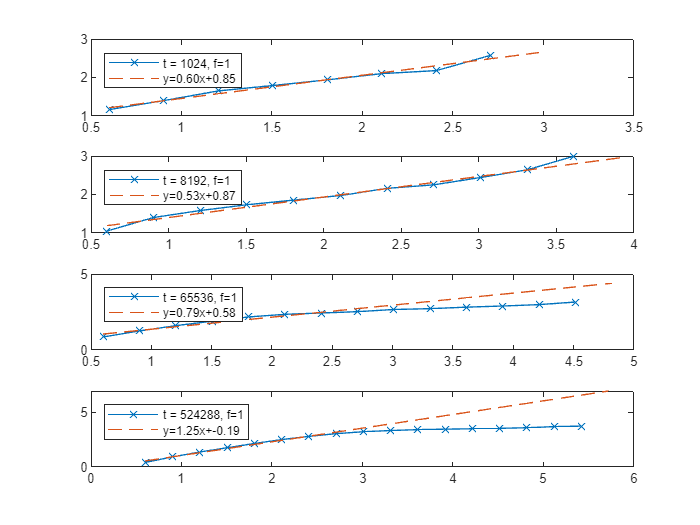

f=1;
target=tiledlayout(4,1);
for e=(10:3:19)
    t=2.^e;
    dfa_path = sprintf("subsample_espacial_temporal\\dfa_t_%d_f_%d.mat", t, f);
    load(dfa_path, "box_lengths", "F");

    interv = (box_lengths<=1e3) & ~isnan(F)';
    x = log10(box_lengths(interv));
    y = log10(F(interv));
    fit = polyfit(x, y, 1);
    yfit = polyval(fit, log10(box_lengths));

    nexttile;
    plot(log10(box_lengths), log10(F), "-x");
    hold on
    plot(log10(box_lengths), yfit, "--");
    legend([sprintf("t = %d, f=%d", t, f)], sprintf("y=%.2fx+%.2f", fit(1), fit(2)), "Location", "northwest");
end
plot_path = sprintf('subsample_espacial_temporal\\figuras\\t_varios_pwr2_f_%d.png', f);
exportgraphics(target, plot_path, 'Resolution', 300);

f=16;
target=tiledlayout(1,1);
alphas=[]


alphas =

     []



E=(8:19)

E =      8     9    10    11    12    13    14    15    16    17    18    19


for e=E
    t=2.^e;
    dfa_path = sprintf("subsample_espacial_temporal\\dfa_t_%d_f_%d.mat", t, f);
    load(dfa_path, "box_lengths", "F");

    interv = (box_lengths<=1e3) & ~isnan(F)';
    x = log10(box_lengths(interv));
    y = log10(F(interv));
    fit = polyfit(x, y, 1);
    alphas(end+1) = fit(1);
end
nexttile;
plot(E, alphas, "--o")
xlabel('$log_2(t)$','Interpreter','latex');
ylabel('$\alpha$','Interpreter','latex');
legend(sprintf("f=%d", f), "Location", "northwest");
plot_path = sprintf('subsample_espacial_temporal\\figuras\\alphas_f_%d.png', f);
exportgraphics(target, plot_path, 'Resolution', 300);

target=tiledlayout(1,1);
E=(8:19);
nexttile;
ff = [1,2,16];
for f=ff
    alphas=[];
    for e=E
        t=2.^e;
        dfa_path = sprintf("subsample_espacial_temporal\\dfa_t_%d_f_%d.mat", t, f);
        load(dfa_path, "box_lengths", "F");
    
        interv = (box_lengths<=1e3) & ~isnan(F)';
        x = log10(box_lengths(interv));
        y = log10(F(interv));
        fit = polyfit(x, y, 1);
        alphas(end+1) = fit(1);
    end
    
    plot(E, alphas, "--o")
    hold on
end


alphas =

     []


alphas =

     []


alphas =

     []



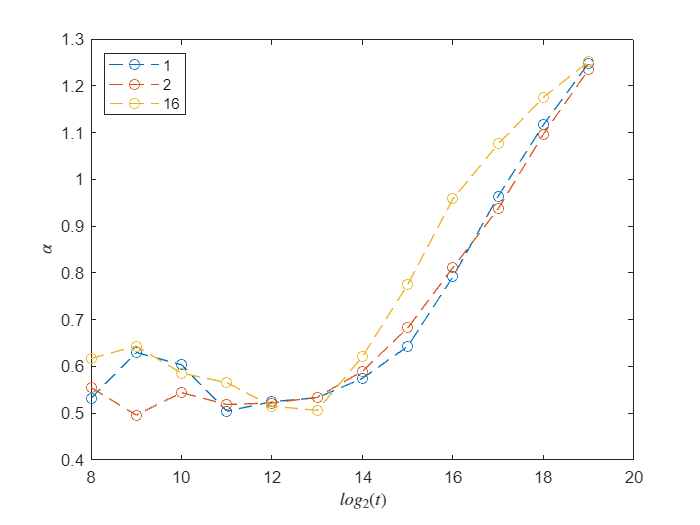

xlabel('$log_2(t)$','Interpreter','latex');
ylabel('$\alpha$','Interpreter','latex');
legend(string(ff), "Location", "northwest");
plot_path = sprintf('subsample_espacial_temporal\\figuras\\alphas_f_varios.png');
exportgraphics(target, plot_path, 'Resolution', 300);

clear gamma
clf
fig.Position = [100, 100, 1200, 900];
target = tiledlayout(1, 1);
E=(8:19);
ff = [1, 2, 16];
nexttile;
for f=ff
    gamma = [];
    for e=E
        t=2^e;
        ava_path = sprintf("subsample_espacial_temporal\\ava_t_%d_f_%d.mat", t, f);
        load(ava_path, "durations", "sizes");
        [D, S] = mean_by_group(durations, sizes);

        if size(D) < 2
            gamma(end+1) = Inf;
        else
            P = polyfit(log(D),log(S),1);
            gamma(end+1) = P(1);
        end
    end
    plot(E(gamma~=Inf), gamma(gamma~=Inf), "--o");
    hold on
end
xlabel('$log_2(t)$','Interpreter','latex');
ylabel('$\gamma$','Interpreter','latex');
legend(string(ff), "Location", "northwest");
plot_path = sprintf('subsample_espacial_temporal\\figuras\\gammas_f_varios.png');
exportgraphics(target, plot_path, 'Resolution', 300);